## Image loading

img = imread('Important_files/film1_big.jpg');

img_crop_height = 1:(size(img,1)/5)-2;
img_crop_width = (size(img,2)/3)+2:(2*size(img,2)/3)-5;

img_rgb = img(img_crop_height,img_crop_width,:);
img_rc = img(img_crop_height,img_crop_width,1);
img_gc = img(img_crop_height,img_crop_width,2);
img_bc = img(img_crop_height,img_crop_width,3);

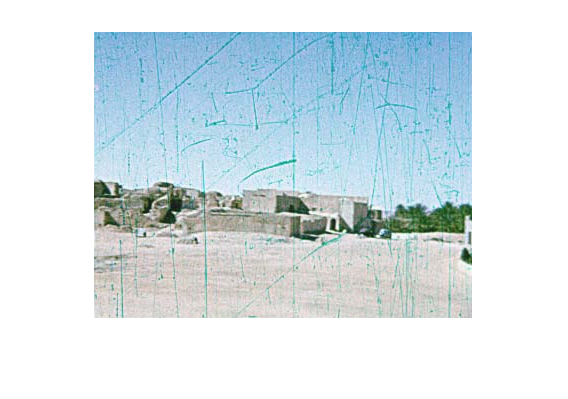

imshow(img_rgb,[]);

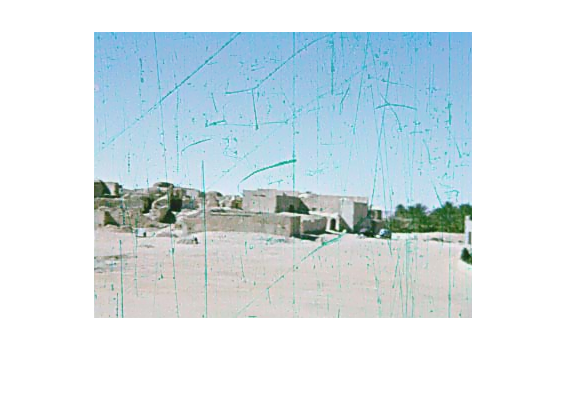

% Om du ser detta så är detta funktioner som verkar finnas för att göra
% liknande det vi vill :)
imshow(locallapfilt(img_rgb,0.1,4),[]);

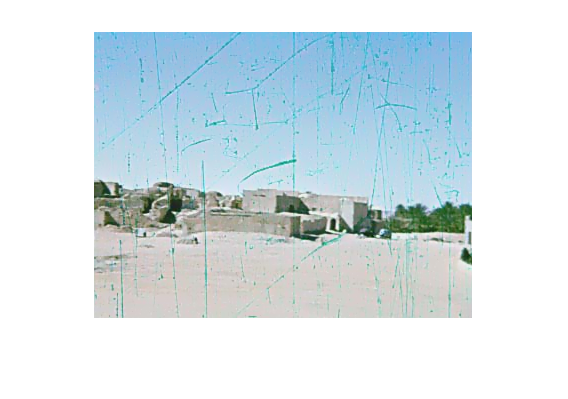

imshow(locallapfilt(img_rgb,0.1,10),[]);

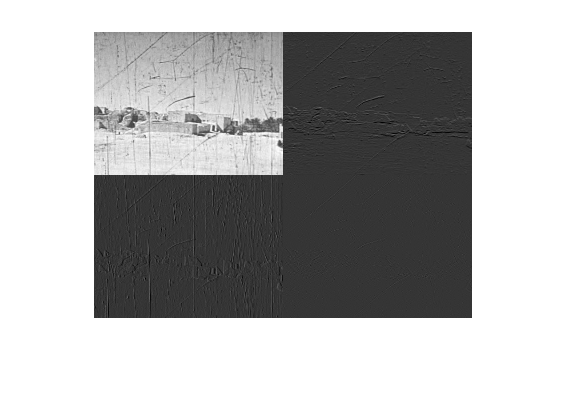

[cA, cH, cV, cD] = dwt2(double(img_rc), 'haar');
imshow([cA, cH; cV, cD],[]);

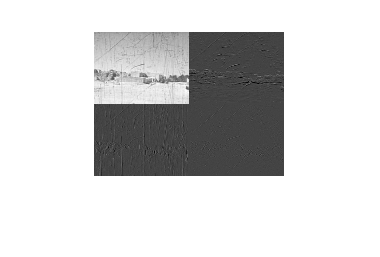

[cA2, cH2, cV2, cD2] = dwt2(double(cA), 'haar');
imshow([cA2, cH2; cV2, cD2],[]);

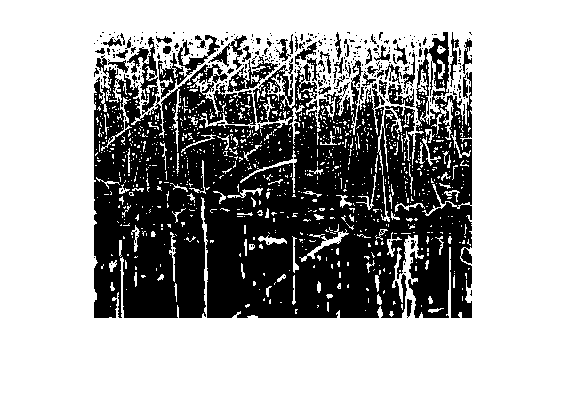

% Masks for Color channels
%color_mask = rgbmask(img_rgb); %RGB
color_mask = hsvmask(img_rgb); %HSV
imshow(color_mask,[])

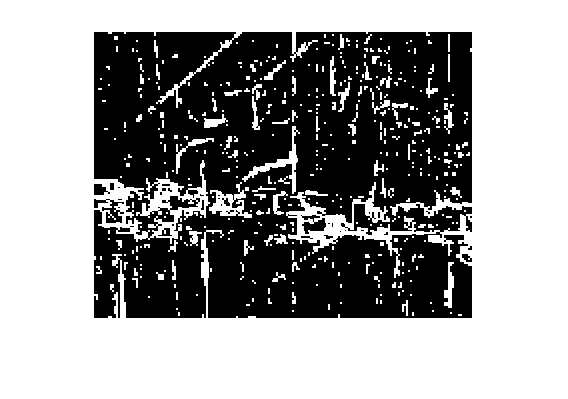


details_mask = detailsmask(img_rgb);
imshow(details_mask,[])

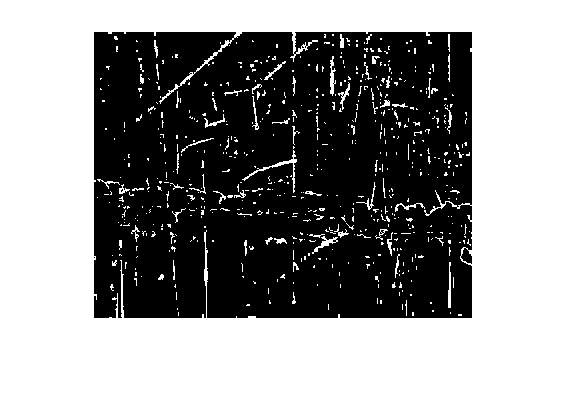


scratch_mask = details_mask & color_mask;
imshow(scratch_mask, [])


% subplot(1,3,1)
% imshow(color_mask, [])
% title('Colormask')
%
% subplot(1,3,2)
% imshow(details_mask, [])
% title('Detailmask')
%
% subplot(1,3,3)
% imshow(scratch_mask, [])
% title('Combined')

[sz_rows, sz_cols] = size(scratch_mask);
[row_idx,col_idx] = find(scratch_mask==1);


H_sz=5;
H_lap = zeros(H_sz);
H_center = uint8(H_sz/2);
padding = double(H_center-1);
H_lap(H_center-1:H_center+1,H_center-1:H_center+1) = fspecial('laplacian',0.5);
H_lap(H_center-1:H_center+1,H_center-1:H_center+1) = [0,-1,0; -1,4,-1; 0,-1,0];
% H_lap =     [0,0,1,0,0;
%              0,1,2,1,0;
%              1,2,-16,2,1;
%              0,1,2,1,0;
%              0,0,1,0,0]
%
%H_lap(H_center,H_center) = 1 - sz^2;

lap_rest = img_rgb;
mean_rest = img_rgb;

for i = 1:numel(row_idx)
    r = row_idx(i);
    c = col_idx(i);
    r_min = max(1, r - padding);
    r_max = min(srows, r + padding);
    c_min = max(1, c - padding);
    c_max = min(scols, c + padding);
    rows = r_min:r_max;
    cols = c_min:c_max;
    
    BW_neighbors = scratch_mask(rows, cols, :);
    RGB_neighbors = img_rgb(rows, cols, :);
    O_neighbors = double(RGB_neighbors).*repmat(~BW_neighbors, [1,1,3]);
    
    if ~isequal(size(BW_neighbors),size(H_lap))
        H_lap_cropped = H_lap(H_center-(r-r_min):H_center+(r_max-r),H_center-(c-c_min):H_center+(c_max-c));
        LAP_neighbors = double(RGB_neighbors).*repmat(H_lap_cropped, [1,1,3]);
    else
        LAP_neighbors = double(RGB_neighbors).*repmat(H_lap, [1,1,3]);
    end
     
    lap_rest(r,c,:) = sum(LAP_neighbors,[1 2]);
    mean_rest(r,c,:) = sum(O_neighbors,[1 2])./(nnz(O_neighbors)/3);
end

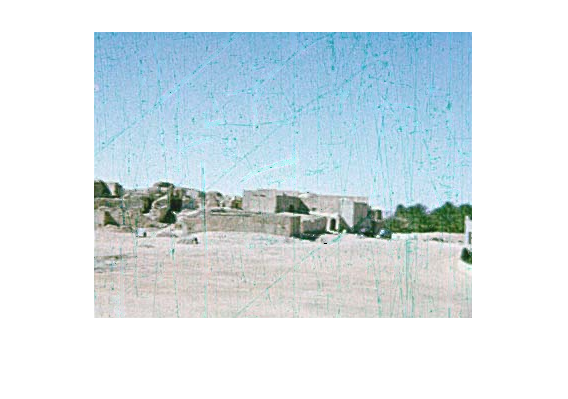

imshow(mean_rest,[])

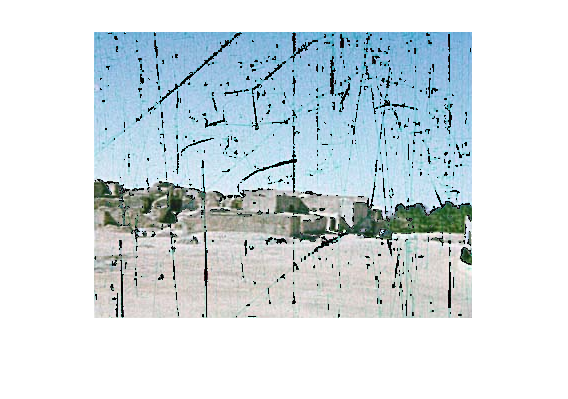

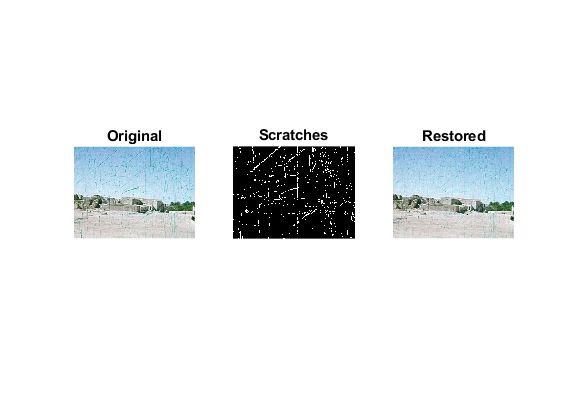

imshow(lap_rest,[])

## **Functions**

function cls = d2bw(c,threshold) % details transformed to binary image with estimated threshold
    if nargin < 2
        threshold = (1-graythresh(abs(c)))*max(max(abs(c)));
    end
    cls = abs(c) >= threshold;
end

%RGB thresholds
function mask = rgbmask(I)
    red = I(:,:,1) >= 0 & I(:,:,1) <= 162;
    green = I(:,:,2) >= 134 & I(:,:,2) <= 228;
    blue = I(:,:,3) >= 149 & I(:,:,3) <= 211;
    mask = red & green & blue;
end

%HSV threshold
function mask = hsvmask(I)
    I = rgb2hsv(I);
    %old values
    %     hue = I(:,:,1) >= 0.336 & (I(:,:,1) <= 0.563);
    %     saturation = I(:,:,2) >= 0.138;
    %     value = I(:,:,3) >= 0.632 & I(:,:,3) <= 0.883;
    hue = I(:,:,1) >= 0.3 & (I(:,:,1) <= 0.574);
    saturation = I(:,:,2) >= 0.055;
    value = I(:,:,3) >= 0.528 & I(:,:,3) <= 0.899;
    mask = hue & saturation & value;
end

function details_mask = detailsmask(I)
    I_size = size(I(:,:,1));
    details_mask = zeros(I_size);
    for color = 1:3
        [cA, cH, cV, cD] = dwt2(double(I(:,:,color)), 'haar');
        [cA2, cH2, cV2, cD2] = dwt2(double(cA), 'haar');
    
        cV_full = imresize(d2bw(cV), I_size, 'nearest');
        cH_full = imresize(d2bw(cH), I_size, 'nearest');
        cD_full = imresize(d2bw(cD), I_size, 'nearest');
        full1 = cV_full | cH_full | cD_full;
    
        cV2_full = imresize(d2bw(cV2), I_size, 'nearest');
        cH2_full = imresize(d2bw(cH2), I_size, 'nearest');
        cD2_full = imresize(d2bw(cD2), I_size, 'nearest');
        full2 = cV2_full | cH2_full | cD2_full;
    
        details_mask = details_mask | full1 | full2;
    end
end